# Pleasure 2: Spline fits on pleasantness-unpleasantness ratings & BOLD time series data

Purpose: Explore whether spline fits are adequate to capture behavioral valence ratings, and fit them with a spline model.

Here we make a design matrix of (1) 1st C, (2) 2nd C, (3) 1st S, (4) 2nd S of SS, and (5) 2nd S of CS sampled at TR-level.

### Set up paths and load variables

basedir = '/Users/sooahn/Dropbox/2023_SooAhnLee_Pain_Pleasure_Training_Grant/analyses';

% basedir = '/Users/f003vz1/Dropbox (Dartmouth College)/A1_WORKING_ANALYSES/2023_SooAhnLee_Pain_Pleasure_Training_Grant/analyses';

cd(basedir)

datadir = fullfile(basedir, 'data');
resultsdir = fullfile(basedir, 'results');
scriptsdir = fullfile(basedir, 'scripts');

addpath(scriptsdir)

load(fullfile(datadir, 'continuous_rating_61subjs.mat'));
load(fullfile(datadir, 'condition_colors.mat'));
load(fullfile(datadir, '61subj_index.mat'));

n_sub = numel(subjarray);

addpath(genpath('/Users/sooahn/Desktop/fdaM'));
rmpath(genpath('/Users/sooahn/Desktop/fdaM/examples'));

**Description of variables:**

rat = ratings, 0 = neutral, -1 = strongest imaginable unpleasantness, 1 = strongest imaginable pleasantness

c0 = capsaicin only

cc = capsaicin twice

cs = caps. then sweet chocolate

ctrl = water only (continuous)

Sampling rate: Ratings are sampled at TR = 0.46 

Events times:

    1.5 min after first sample, 1.5 min * 60 sec * 1/0.46 sampling rate = 196

    7 min after first sample, 7 min * 60 sec * 1/0.46 sampling rate = 913

**Prepare some variables**

TR = 0.46;

evt1 = 196;
evt2 = 913;

tr_len = 1875;

rat_comb = [c0_rat'; cc_rat'; cs_rat'; ss_rat'];

## Build a design matrix

degree = 8; % number of basis functions; higher = more spatial resolution. Must be at least k.
dt = 0.0288;
order = 3;

#### We will exclude the first 2 & last 2 curves.

- The first & last curves are for the signals starting and ending at non-zero time point.

- The second-first & -last curves: not symmetric. We won't use the splines with not identical increase & drop rates.

Create a set of splines for 'C1' events: 

windowlen_c1 = 47; 

% bf_c1 = Bspline(1:ceil(windowlen_c1 ./ TR),k,[ones(1,k-1) linspace(1,ceil(windowlen_c1 ./ TR)+0.1,degree-1) (ceil(windowlen_c1 ./ TR)+0.1)*ones(1,k-1)]);
basis = create_bspline_basis([0,windowlen_c1/dt], degree+4, order);    
bf_c1 = full(eval_basis((1:windowlen_c1/dt),basis));
bf_c1 = bf_c1(:,3:end-2);

Create a set of splines for 'C2' events:

windowlen_c2 = 26; 

% bf_c2 = Bspline(1:ceil(windowlen_c2 ./ TR),k,[ones(1,k-1) linspace(1,ceil(windowlen_c2 ./ TR)+0.1,degree-1) (ceil(windowlen_c2 ./ TR)+0.1)*ones(1,k-1)]);
basis = create_bspline_basis([0,windowlen_c2/dt], degree+4, order);    
bf_c2 = full(eval_basis((1:windowlen_c2/dt),basis));
bf_c2 = bf_c2(:,3:end-2);

Create a set of splines for 'S1' events: 

windowlen_s1 = 20; 

% bf_s1 = Bspline(1:ceil(windowlen_s1 ./ TR),k,[ones(1,k-1) linspace(1,ceil(windowlen_s1 ./ TR)+0.1,degree-1) (ceil(windowlen_s1 ./ TR)+0.1)*ones(1,k-1)]);
basis = create_bspline_basis([0,windowlen_s1/dt], degree+4, order);    
bf_s1 = full(eval_basis((1:windowlen_s1/dt),basis));
bf_s1 = bf_s1(:,3:end-2);

Create a set of splines for 'S2 of SS' events:

windowlen_s2_ss = 26;

% bf_s2_ss = Bspline(1:ceil(windowlen_s2_ss ./ TR),k,[ones(1,k-1) linspace(1,ceil(windowlen_s2_ss ./ TR)+0.1,degree-1) (ceil(windowlen_s2_ss ./ TR)+0.1)*ones(1,k-1)]);
basis = create_bspline_basis([0,windowlen_s2_ss/dt], degree+4, order);    
bf_s2_ss = full(eval_basis((1:windowlen_s2_ss/dt),basis));
bf_s2_ss = bf_s2_ss(:,3:end-2);

Create a set of splines for 'S2 of CS' events:

windowlen_s2_cs = 26;

% bf_s2_cs = Bspline(1:ceil(windowlen_s2_cs ./ TR),k,[ones(1,k-1) linspace(1,ceil(windowlen_s2_cs ./ TR)+0.1,degree-1) (ceil(windowlen_s2_cs ./ TR)+0.1)*ones(1,k-1)]);
basis = create_bspline_basis([0,windowlen_s2_cs/dt], degree+4, order);    
bf_s2_cs = full(eval_basis((1:windowlen_s2_cs/dt),basis));
bf_s2_cs = bf_s2_cs(:,3:end-2);

### Plot the final design matrix:

names = {'Capsaicin1' 'Capsaicin2' 'Sweet1' 'Sweet2_Sweet' 'Sweet2_Caps'};

total_len = tr_len * 4;


% c1
ons = {};
ons{1} = [evt1 evt1 + tr_len evt1 + tr_len*2]'; % including a dummy run every other run


% Design matrix has concatenated runs
X_c1 = onsets2fmridesign(ons, 1, total_len, bf_c1);


% c2
ons = {};
ons{1} = [evt2 + tr_len];


% Design matrix has concatenated runs
X_c2 = onsets2fmridesign(ons, 1, total_len, bf_c2);


% s1
ons = {};
ons{1} = [evt1 + tr_len*3];


X_s1 = onsets2fmridesign(ons, 1, total_len, bf_s1);


% s2_ss
ons = {};
ons{1} = [evt2 + tr_len*3];


X_s2_ss = onsets2fmridesign(ons, 1, total_len, bf_s2_ss);


% s2_cs
ons = {};
ons{1} = [evt2 + tr_len*2];


X_s2_cs = onsets2fmridesign(ons, 1, total_len, bf_s2_cs);


% concat
X = [X_c1 X_c2 X_s1 X_s2_ss X_s2_cs];

% wh_dummy = [1+tr_len:tr_len*2 1+tr_len*3:tr_len*4 1+tr_len*5:tr_len*6 1+tr_len*7:tr_len*8];
% X(wh_dummy,:) = [];

vif = getvif(X,0);


X = [X blkdiag(ones(tr_len,1),ones(tr_len,1),ones(tr_len,1),ones(tr_len,1))];

% CC, C0, CS-specific intercept
X = [X [ones(tr_len*3,1); zeros(tr_len,1)]];


figure; plot_matrix_cols(X)

ans =   1×50 Line array:

  Columns 1 through 44

    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line    Line

  Columns 45 through 50

    Line    Line    Line    Line    Line    Line


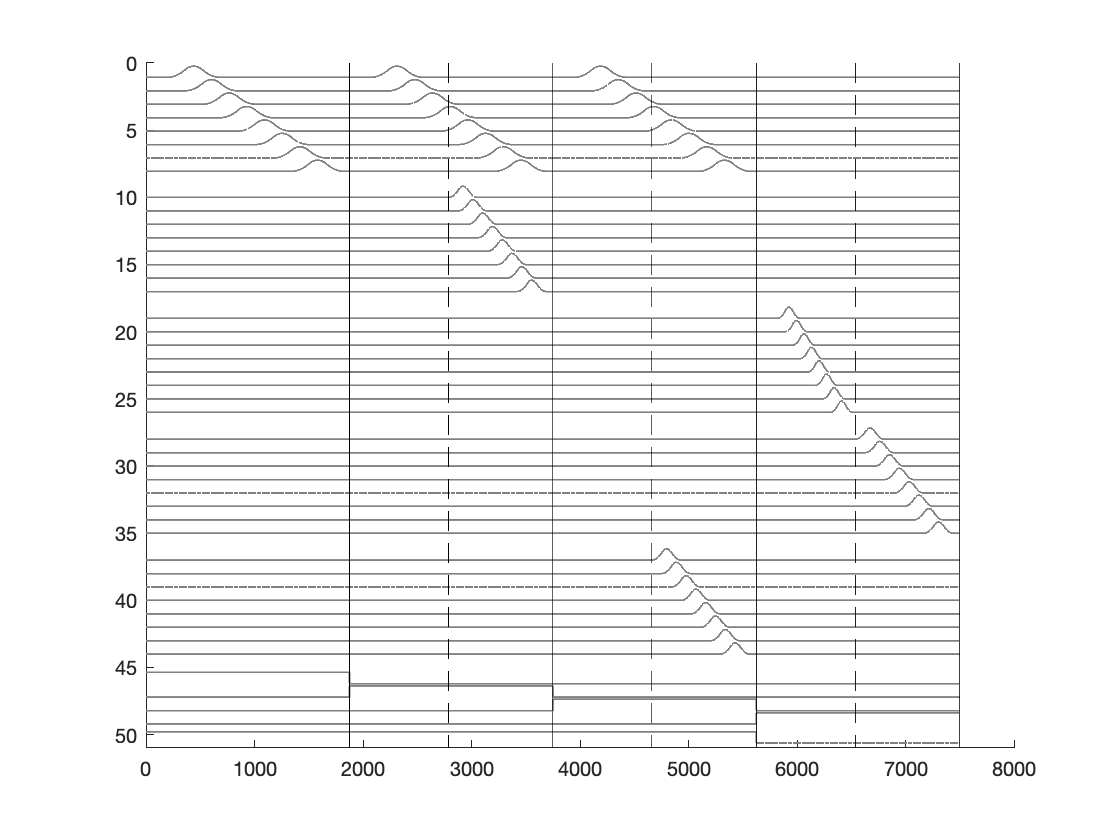

plot_vertical_line(tr_len);
hh = plot_vertical_line(tr_len+evt2); set(hh, 'LineStyle', '--');
plot_vertical_line(tr_len*2);
hh = plot_vertical_line(tr_len*2+evt2); set(hh, 'LineStyle', '--');
plot_vertical_line(tr_len*3);
hh = plot_vertical_line(tr_len*3+evt2); set(hh, 'LineStyle', '--');
plot_vertical_line(tr_len*4);

### Save

% save(fullfile(datadir,'design_matrix_trlevel_fdam.mat'),'X','bf*');